# Task Two - Integral Method - Two Unknows

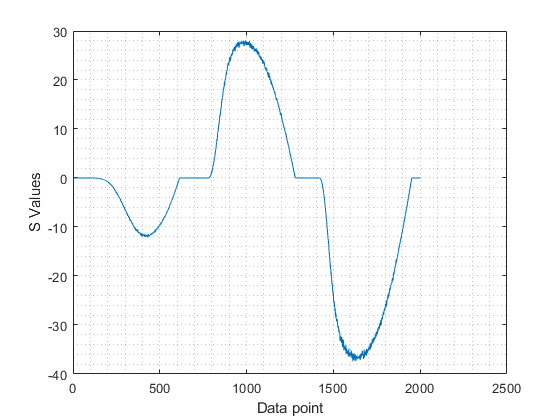

clear
clc

data = load('StudentID_number35352633.mat');
%constants
m = data(1).Mass;
matrix = data(1).Project_Data;
c = data(1).Damping;
[n,p] = size(matrix);

%variables
dvg = matrix(:,1); 
v = matrix(:,2); 
dv = matrix(:,3); 
ddv = matrix(:,4);
z = matrix(:,5); % Hysteric component
% partitions
partition = 3;

% The C function derived from the differential function
C = -0.5*dv.*(sign(dv.*z) + ones(2001,1)).*z.^2; plot(C); xlabel('Data point'); ylabel('S Values'); grid minor;

delta_t = 0.005; % timestamp the 

x1 = (delta_t/2)*(C(1) + C(2001) + 2*sum(C(2:2000)));
x2 = (delta_t/2)*(C(1) + C(333) + 2*sum(C(2:332)));
x3 = (delta_t/2)*(C(334) + C(667) + 2*sum(C(335:666)));
x4 = (delta_t/2)*(C(668) + C(1001) + 2*sum(C(667:1000)));
x5 = (delta_t/2)*(C(1002) + C(1335) + 2*sum(C(1003:1334)));
x6 = (delta_t/2)*(C(1336) + C(1669) + 2*sum(C(1335:1668)));
x7 = (delta_t/2)*(C(1670) + C(2001) + 2*sum(C(1671:2000)));

y1 = z(2001) - z(1) - v(2001) + v(1);
y2 = z(333) - z(1) - v(333) + v(1);
y3 = z(667) - z(334) - v(667) + v(334);
y4 = z(1001) - z(668) - v(1001) + v(668);
y5 = z(1335) - z(1002) - v(1335) + v(1002);
y6 = z(1669) - z(1336) - v(1669) + v(1336);
y7 = z(2001) - z(1670) - v(1670) + v(1337);

Y = [y1 y2 y3 y4 y5 y6].';
X = [x1 x2 x3 x4 x5 x6].';

% Thus
K = (inv(X.'*X))*(X.'*Y);

% Therefore
dy = sqrt(1/K);